# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### Connectivity Methods:

### Graph Theory:

In graph theory, networks can be represented as matrices or as graphs. Matrices and graphs have vertices (also sometimes called nodes), and they have edges that represent connections among vertices. 

In terms of EEG connectivity, *vertices correspond to electrodes*, and *edges correspond to some measure of connectivity between pairs of electrodes.* 

Matrices and graphs contain identical information regarding the vertices and edges of the network but show the information in different ways. Matrices are useful for visualizing large networks, although they generally contain no meaningful information about relative spatial positions among vertices. Graphs can contain information regarding the topology and relative locations of the vertices.

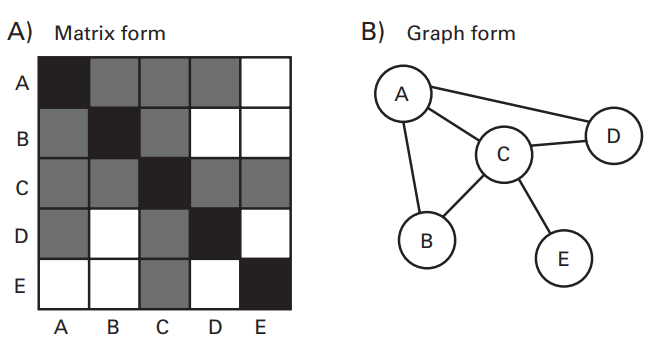  

% load data
load sampleEEGdata

% specify some time-frequency parameters
center_freq   = 10; % Hz
time2analyze  = 200; % in ms

% wavelet and FFT parameters
time          = -1:1/EEG.srate:1;
half_wavelet  = (length(time)-1)/2;
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;

% initialize connectivity output matrix
connectivitymat = zeros(EEG.nbchan,EEG.nbchan);

% time in indices
[junk,tidx] = min(abs(EEG.times-time2analyze));

% create wavelet and take FFT
s = 5/(2*pi*center_freq);
wavelet_fft = fft( exp(2*1i*pi*center_freq.*time) .* exp(-time.^2./(2*(s^2))) ,n_convolution);

% compute analytic signal for all channels
analyticsignals = zeros(EEG.nbchan,EEG.pnts,EEG.trials);
for chani=1:EEG.nbchan
    
    % FFT of data
    data_fft = fft(reshape(EEG.data(chani,:,:),1,n_data),n_convolution);
    
    % convolution
    convolution_result = ifft(wavelet_fft.*data_fft,n_convolution);
    convolution_result = convolution_result(half_wavelet+1:end-half_wavelet);
    
    analyticsignals(chani,:,:) = reshape(convolution_result,EEG.pnts,EEG.trials);
end

% now compute all-to-all connectivity
for chani=1:EEG.nbchan
    for chanj=chani:EEG.nbchan % note that you don't need to start at 1
        xsd = squeeze(analyticsignals(chani,tidx,:) .* conj(analyticsignals(chanj,tidx,:)));
        
        % connectivity matrix (phase-lag index on upper triangle; ISPC on lower triangle)
        connectivitymat(chani,chanj) = abs(mean(sign(imag(xsd))));
        connectivitymat(chanj,chani) = abs(mean(exp(1i*angle(xsd))));
    end
end

figure
imagesc(connectivitymat)
set(gca,'clim',[0 .7],'xtick',1:8:EEG.nbchan,'xticklabel',{EEG.chanlocs(1:8:end).labels},'ytick',1:8:EEG.nbchan,'yticklabel',{EEG.chanlocs(1:8:end).labels});
axis square
colorbar

Figure shows a connectivity matrix for real EEG data. The *x*- and *y*-axes both reflect electrodes, and the grayscale intensity at each pixel corresponds to the strength of phasebased connectivity between each pair of electrodes.   

Why asymmetric?

The asymmetric connectivity matrix in figure shows connectivity computed using the phase-lag index (upper-right triangle of the matrix) and using intersite phase clustering over trials (ISPC-trials; lower-left triangle of the matrix).  

In this figure we only had matrice for one frequency. If we want to examine different frequencies, we probably have a huge 5-D hyper cube of data. 

**Exersise 1.**

Extend the above code to incorporate all frequency ranges in time (you need to have a hyper 5D cube)

### **Thresholding Connectivity Matrices**  

The connectivity matrix shown in figure 31.2 is a full matrix, meaning that each point in the two-dimensional space has a nonzero value. Connectivity matrices can also have “ holes” in them if the value at pixels representing subthreshold connectivity are set to zero or NaN. These are called *thresholded connectivity matrices and are useful for computing several graph theory metrics* including connectivity degree, clustering coefficient, and small-world networks.  

In these cases a **liberal threshold based on data distributions is appropriate**. For example, you could select a threshold of one standard deviation above the median connectivity value.

figure

subplot(221)
% get upper part of matrix
temp = nonzeros(triu(connectivitymat));
temp(temp==1)=[]; % clear 1's from the diagonal

% threshold is one std above median connectivity value
pli_thresh = std(temp)+median(temp);

% plot histogram and vertical line at threshold
[y,x] = hist(temp,30);
h = bar(x,y,'histc');
hold on
plot([pli_thresh pli_thresh],get(gca,'ylim'),'m','linew',2)

% make nice
set(h,'linestyle','none')
set(gca,'xtick',0:.2:1,'xlim',[0 1])
xlabel('Phase-lag index'), ylabel('Count')



subplot(222)
% get upper part of matrix
temp = nonzeros(tril(connectivitymat));
temp(temp==1)=[]; % clear 1's on the diagonal

% find 1 std above median connectivity value
ispc_thresh = std(temp)+median(temp);

% plot histogram and vertical line at threshold
[y,x] = hist(temp,30);
h=bar(x,y,'histc');
hold on
plot([ispc_thresh ispc_thresh],get(gca,'ylim'),'m','linew',2)

% make nice
set(h,'linestyle','none')
set(gca,'xtick',0:.2:1,'xlim',[0 1])
xlabel('ISPC'), ylabel('Count')


subplot(223)

% make symmetric phase-lag index connectivity matrix
pli_mat = connectivitymat;
pli_mat(logical(tril(pli_mat))) = 0; % eliminate lower triangle
pli_mat = pli_mat + triu(pli_mat)';  % mirror lower triangle to upper triangle
pli_mat(pli_mat<pli_thresh)=0;
imagesc(pli_mat)
set(gca,'clim',[0 .7],'xtick',1:8:EEG.nbchan,'xticklabel',{EEG.chanlocs(1:8:end).labels},'ytick',1:8:EEG.nbchan,'yticklabel',{EEG.chanlocs(1:8:end).labels});
axis square


subplot(224)

% make symmetric phase-lag index connectivity matrix
ispc_mat = connectivitymat;
ispc_mat(logical(triu(ispc_mat))) = 0; % eliminate lower triangle
ispc_mat = ispc_mat + tril(ispc_mat)';  % mirror lower triangle to upper triangle
ispc_mat(ispc_mat<ispc_thresh)=0;
imagesc(logical(ispc_mat)) % logical converts to 0's and 1's, thus binarizing connectivity matrix
set(gca,'clim',[0 .7],'xtick',1:8:EEG.nbchan,'xticklabel',{EEG.chanlocs(1:8:end).labels},'ytick',1:8:EEG.nbchan,'yticklabel',{EEG.chanlocs(1:8:end).labels});
axis square

### Connectivity Degree

Connectivity degree (also sometimes simply called degree) is a simple but informative measure of the extent to which a** vertex acts as a “ hub ” or intersection for many connections** (think of the difference in flight connections between London Heathrow Airport and Knuffingen Airport). Computing connectivity degree is straightforward: for each electrode, **count the number of suprathreshold connections, regardless of the location of those connections** (figure 31.5 ). Do not count each vertex in its own degree value. These “ raw ” summed connectivity degree values can be scaled to percentages or fractions of the total number of electrodes minus one (minus one because you do not count autoconnectivity).  Once you have counted the number of suprathreshold connections for each electrode, you no longer have an electrodes-by-electrodes matrix but rather, a 1-by-electrodes vector of numbers. 

figure
subplot(121)
% note: logical() below converts the matrix to 0's and 1's
topoplot(sum(logical(pli_mat)),EEG.chanlocs,'plotrad',.53,'maplimits',[0 25]);
title('Connectivity degree, phase-lag index')

subplot(122)
topoplot(sum(logical(ispc_mat)),EEG.chanlocs,'plotrad',.53,'maplimits',[0 25]);
title('Connectivity degree, ISPC')



#### Over time Connectivity degree on two freq

frex = logspace(log10(3),log10(40),25);
times2save = -300:50:1200;
thresh = zeros(size(frex)); % added threshold vector

% wavelet and FFT parameters
time          = -1:1/EEG.srate:1;
half_wavelet  = (length(time)-1)/2;
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv2       = pow2(nextpow2(n_convolution));

% create wavelet (and take FFT)
wavelets_fft = zeros(length(frex),n_conv2);
s = logspace(log10(4),log10(10),length(frex))./(2*pi.*frex);
for fi=1:length(frex)
    wavelets_fft(fi,:) = fft( exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*(s(fi)^2))) ,n_conv2);
end

% find time indices
times2saveidx = dsearchn(EEG.times',times2save');

% initialize matrices
alldata    = zeros(EEG.nbchan,length(frex),length(times2save),EEG.trials);
tf_all2all = zeros(EEG.nbchan,EEG.nbchan,length(frex),length(times2save));
tf_degree  = zeros(EEG.nbchan,length(frex),length(times2save));

% first, run convolution for all electrodes and save results
for chani=1:EEG.nbchan
    
    % FFT of activity at this electrode (note that 
    % this is done outside the frequency loop)
    eeg_fft = fft(reshape(EEG.data(chani,:,:),1,[]),n_conv2);
    
    % loop over frequencies
    for fi=1:length(frex)
        
        % analytic signal from target
        conv_res = ifft(wavelets_fft(fi,:).*eeg_fft,n_conv2);
        conv_res = conv_res(1:n_convolution);
        asig     = reshape(conv_res(half_wavelet+1:end-half_wavelet),EEG.pnts,EEG.trials);
        
        % store the required time points
        alldata(chani,fi,:,:) = asig(times2saveidx,:);
    end % end frequency loop
end % end channel loop


% now that we have all the data, compute all-to-all connectivity
for chani=1:EEG.nbchan
    for chanj=chani+1:EEG.nbchan
        
        % compute connectivity
        xsd = squeeze(alldata(chani,:,:,:).*conj(alldata(chanj,:,:,:)));
        
        % connectivity matrix (phase-lag index or ISPC; comment one or the other line)
        % tf_all2all(chani,chanj,:,:) = abs(mean(sign(imag(xsd)),3)); % pli
        tf_all2all(chani,chanj,:,:) = abs(mean(exp(1i*angle(xsd)),3)); % ispc
    end
end

% now that we have a one-to-all connectivity, threshold the 
% connectivity matrix (separate threshold for each frequency
for fi=1:length(frex)
    
    % Note about the threshold: The original code had a bug where the
    % threshold for all analyses and all frequencies was based only on the
    % final frequency. Thanks to Lars Benschop for finding that bug!
    
    tempsynch = nonzeros(tf_all2all(:,:,fi,:));
    thresh(fi) = median(tempsynch) + std(tempsynch);
    
    % isolate, threshold, binarize
    for ti=1:size(tf_all2all,4)
        temp = squeeze(tf_all2all(:,:,fi,ti));
        temp = temp + triu(temp)';      % make symmetric matrix
        temp = temp>thresh(fi);         % threshold and binarize
        tf_degree(:,fi,ti) = sum(temp); % compute degree (sum of suprathreshold connections)
    end
end

%% Figure 31.7 (plotting)

% show topographical maps
freqs2plot = [ 5 9 ]; % Hz
times2plot = [ 100 200 300 ]; % ms
clim = [0 20];

figure
for fi=1:length(freqs2plot)
    for ti=1:length(times2plot)
        
        subplot(length(freqs2plot),length(times2plot),ti+(fi-1)*length(times2plot))
        topoplot(squeeze(tf_degree(:,dsearchn(frex',freqs2plot(fi)),dsearchn(times2save',times2plot(ti)))),EEG.chanlocs,'plotrad',.53,'maplimits',clim,'electrodes','off');
        
        title([ num2str(times2plot(ti)) ' ms, ' num2str(freqs2plot(fi)) ' Hz' ])        
    end
end

%% Figure 31.8 (plotting)

electrode2plot = 'fcz';'oz';
baselineperiod = [ -300 -100 ];
clim = [-10 10];


% convert baseline period time to idx
baseidx = dsearchn(times2save',baselineperiod');
% subtract baseline
tf_degree_base = tf_degree - repmat(mean(tf_degree(:,:,baseidx(1):baseidx(2)),3),[1 1 size(tf_degree,3)]);


figure
contourf(times2save,frex,squeeze(tf_degree_base(strcmpi(electrode2plot,{EEG.chanlocs.labels}),:,:)),20,'linecolor','none')
set(gca,'clim',clim,'yscale','log','ytick',round(logspace(log10(frex(1)),log10(frex(end)),6)))
xlabel('Time (ms)'), ylabel('Frequency (Hz)')
title([ 'TF connectivity degree at electrode ' electrode2plot ])

### **Clustering Coefficient**  

An intuitive way to conceptualize clustering coefficient is to think about social friendships. How many of your friends are friends with each other? If they are all friends with each other,** you have a high clustering coefficient;** if they are scattered throughout the world and do not know each other, you have a low clustering coefficient. In EEG connectivity terms, the clustering coefficient of electrode A is** the proportion of electrodes that have suprathreshold connectivity with electrode A that also have suprathreshold connectivity with each other.** 

in which *i *refers to each electrode, *v ij *is 1 if there is suprathreshold connectivity between electrodes *i *and *j *and 0 otherwise, and *n *is the number of electrodes with suprathreshold connections to electrode *i *(note that this is not the total number of electrodes; it is the connectivity degree of electrode *i*).

**Exercise 2.**

Whats the point of 2 in the equation? when you could remove that?

freqs2plot = [ 5 9 ]; % Hz
times2plot = [ 100 200 300 ]; % ms
clim = [.4 .8];

% open two figures ('h' for handle)
figh1 = figure;
figh2 = figure;

for fi=1:length(freqs2plot)
    for ti=1:length(times2plot)
        
        % frequency index
        fidx = dsearchn(frex',freqs2plot(fi));
        
        % extract thresholded connectivity matrix
        connmat = squeeze(tf_all2all(:,:,fidx,dsearchn(times2save',times2plot(ti))));
        connmat = connmat + triu(connmat)';  % make symmetric matrix
        connmat = connmat>thresh(fidx);      % threshold and binarize
        
        
        % initialize
        clustcoef = zeros(size(EEG.nbchan));
        
        for chani=1:EEG.nbchan
            
            % find neighbors (suprathreshold connections)
            neighbors = find(connmat(chani,:));
            n = length(neighbors);
            
            % cluster coefficient not computed for islands
            if n>1
                % "local" network of neighbors
                localnetwork = connmat(neighbors,neighbors);
                % localnetwork is symmetric; remove redundant values by replacing with NaN
                localnetwork = localnetwork + tril(nan(n));
                
                % compute cluster coefficient (neighbor connectivity scaled)
                clustcoef(chani) = 2*nansum(localnetwork(:)) / ((n-1)*n);
            end
        end
        
        % topoplots
        figure(figh1)
        subplot(length(freqs2plot),length(times2plot),ti+(fi-1)*length(times2plot))
        topoplot(clustcoef,EEG.chanlocs,'plotrad',.53,'maplimits',clim,'electrodes','off');
        title([ 'Cluster coefficient: ' num2str(times2plot(ti)) ' ms, ' num2str(freqs2plot(fi)) ' Hz' ])
        
        % relationship between degree and cluster coefficient
        figure(figh2)
        subplot(length(freqs2plot),length(times2plot),ti+(fi-1)*length(times2plot))
        plot(squeeze(tf_degree(:,dsearchn(frex',freqs2plot(fi)),dsearchn(times2save',times2plot(ti)))),clustcoef,'.')
        [r,p] = corr(squeeze(tf_degree(:,dsearchn(frex',freqs2plot(fi)),dsearchn(times2save',times2plot(ti)))),clustcoef','type','s');
        set(gca,'ylim',[-.05 1.05],'xlim',[0 30])
        xlabel('degree'), ylabel('cluster coefficient')
        title([ 'Correlation: r=' num2str(r) ', p=' num2str(p) ])
        
    end
end


**Path Length**

Path length is the average distance from each vertex (electrode) to any other vertex. For noninvasive EEG recordings, path length has a limited physiological interpretation because there are many nodes in the brain through which information can transfer, and many of those are not measurable with EEG (e.g., thalamic nuclei). However, path length is one of the two key metrics for assessing whether a network has “ small-world” characteristics. 

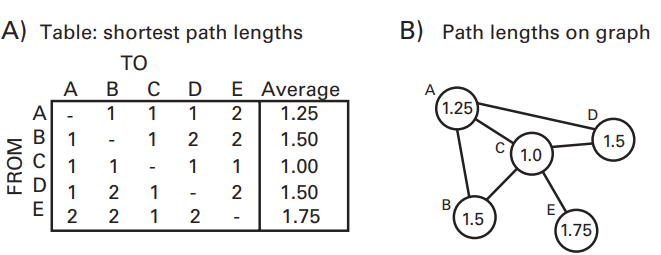

Small-world networks are characterized by** higher clustering coefficient and lower path length** than would be expected by chance. Many efficient networks, ranging from airline connections to electrical power grids to neural systems, seem to be organized as a small-world network (Buchanan 2003).  

A formal test for evaluating whether a network conforms to a small-world network (Humphries and Gurney 2008) involves a double ratio: the numerator is the ratio* of the observed average clustering coefficient* to that of a random network, and the denominator is the ratio of the observed* average path length to that of a random network*  

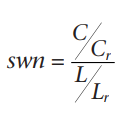

in which *C *refers to clustering coefficient, *L *refers to path length, and the subscript *r *refers to a random network. ***If the swn value is greater than 1, the network can be said to exhibit properties consistent with a small-world network.   ***

The statistical significance of the *swn *value in equation 31.2 can be evaluated via permutation testing. At each iteration during the permutation testing, a random network is created by a network with the *same number of connections as the observed network, but those connections are randomly rewired.* Next, the *swn *value is recomputed, replacing the C and L terms in equation 31.2 with other random networks. After equation 31.2 has been evaluated repeatedly over many random networks, a distribution of *swn *values is created under the null hypothesis that the networks have a random organization. Next, the *swn *value observed in the unadulterated connectivity data can be compared against this null hypothesis distribution to obtain a statistical value in normal *Z *standard deviation units. (This is done by subtracting the mean of the distribution and dividing by the standard deviation.)   

freq2use = 6;
time2use = 300;
n_permutations = 1000;

thresholds=linspace(0,2,20);
swn_z = zeros(size(thresholds));

for threshi=1:length(thresholds)
    
    % frequency index
    fidx = dsearchn(frex',freq2use);
    
    connmat = squeeze(tf_all2all(:,:,fidx,dsearchn(times2save',time2use)));
    tmpsynch = nonzeros(tf_all2all(:,:,fidx,:));
    tthresh = median(tmpsynch)+thresholds(threshi)*std(tmpsynch);
    connmat = connmat + triu(connmat)';  % make symmetric matrix
    connmat = connmat>tthresh;           % threshold and binarize
    nconnections = sum(connmat(:))/2;    % number of connections (for random network)
    
    % find locations of lower triangle
    matrix_locs = find(tril(connmat+1-eye(length(connmat))));
    
    swn_permutations  = zeros(1,n_permutations);
    swn_permutations2 = zeros(1,n_permutations);
    
    
    
    % compute real cluster coefficient and path lengths
    clustcoef_real = zeros(1,EEG.nbchan);
    for chani=1:EEG.nbchan
        neighbors = find(connmat(chani,:));
        n = length(neighbors);
        if n>1
            localnetwork = connmat(neighbors,neighbors);
            localnetwork = localnetwork + tril(nan(n));
            clustcoef_real(chani) = 2*nansum(localnetwork(:)) / ((n-1)*n);
        end
    end
    % average clustering coefficient over channels
    clustcoef_real = nanmean(clustcoef_real);
    
    % average path length (remove zeros and Inf's)
    temppathlengths = nonzeros(pathlength(double(connmat)));
    pathlengths_real = mean(temppathlengths(isfinite(temppathlengths)));
    
    
    
    
    % first create 1000 random graphs and compute their CC and PL
    clustercoefficients_random = zeros(1,n_permutations);
    pathlengths_random = zeros(1,n_permutations);
    
    for permi=1:n_permutations
        
        % generate random network...
        connmat_random = zeros(size(connmat));
        edges2fill     = randsample(matrix_locs,nconnections);
        connmat_random(edges2fill) = 1;
        % mirror matrix
        connmat_random = logical(tril(connmat_random) + tril(connmat_random)');
        
        clustcoef_random  = zeros(1,EEG.nbchan);
        for chani=1:EEG.nbchan
            neighbors = find(connmat_random(chani,:));
            n = length(neighbors);
            if n>1
                localnetwork = connmat_random(neighbors,neighbors);
                localnetwork = localnetwork + tril(nan(n));
                clustcoef_random(chani) = 2*nansum(localnetwork(:)) / ((n-1)*n);
            end
        end
        clustercoefficients_random(permi) = nanmean(clustcoef_random);
        
        % average path length (remove zeros and Inf's)
        temppathlengths = nonzeros(pathlength(double(connmat_random)));
        pathlengths_random(permi) = mean(temppathlengths(isfinite(temppathlengths)));
    end
    
    % now compute permuted small-world-network-ness
    for permi=1:n_permutations
        whichnetworks2use = randsample(1:n_permutations,2);
        swn_permutations(permi)  = ( clustercoefficients_random(whichnetworks2use(1))/clustercoefficients_random(whichnetworks2use(2)) ) / ( pathlengths_random(whichnetworks2use(1))/pathlengths_random(whichnetworks2use(2)) );
    end
    
    
    % true swn and its z-value
    swn_real       = ( clustcoef_real/mean(clustercoefficients_random) ) / ( pathlengths_real/mean(pathlengths_random) );
    swn_z(threshi) = (swn_real-mean(swn_permutations))/std(swn_permutations);
    
    if threshi==length(thresholds)/2
        figure
        [y,x] = hist(swn_permutations,50);
        h=bar(x,y,'histc');
        set(h,'linestyle','none')
        hold on
        plot(repmat(swn_real,1,2),get(gca,'ylim')/2,'m','linew',3)
        title([ 'Small-world-networkness: Z=' num2str(swn_z(threshi)) ', p=' num2str(1-normcdf(abs(swn_z(threshi)))) ])
    end
end

figure
plot(thresholds,swn_z,'-o','markerface','w')
xlabel('Threshold (Standard deviations above median)')
ylabel('SWN_z')
set(gca,'xlim',[-.05 2.05])

Whether a network can be considered significantly small-world-like is influenced by several factors, including the connectivity method used, network size (small-world-ness increases as a function of the number of nodes; Humphries and Gurney 2008), and other parameters (Telesford et al. 2011). Small-world-ness is also sensitive to the binarizing threshold.  

**Exercise 3**

1. Pick two frequency bands and two time segments (e.g., pretrial and poststimulus or early poststimulus and late poststimulus). Compute connectivity degree and clustering coefficient separately for the first 40 and the last 40 trials from the two frequency bands and the two time segments, and show the results in topographical plots. Are there visually salient differences in network properties between the first and the last 40 trials? How would you interpret the results if they were statistically significant?

2. Pick two frequency bands and test whether small-world-ness changes over time in those frequency bands. Make sure the binarizing threshold is constant over time within each frequency, but it can be different for the two frequency bands  